# Voltage and Current Versus Time With Sinusoidal Voltage Source

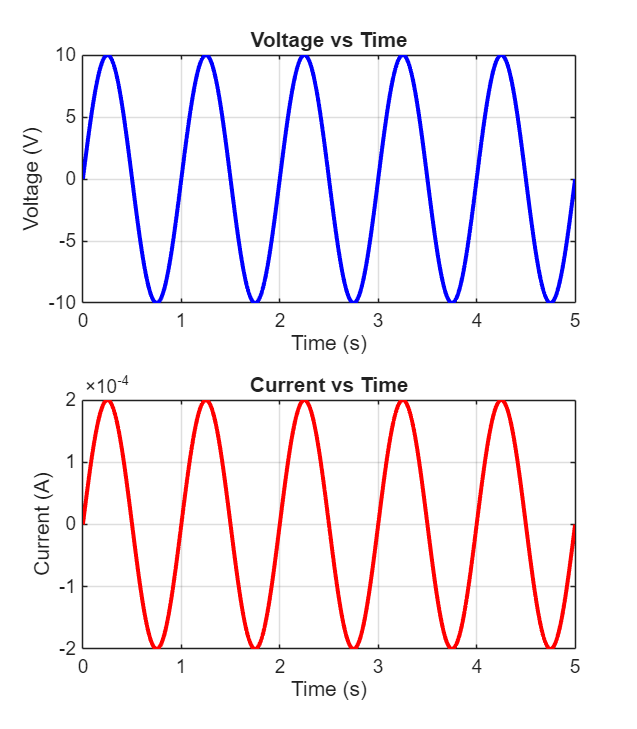

%{
ES115: Voltage and Current Versus Time With Sinusoidal Voltage Source
Author: Jack O'charek
Date: 4-28-26
Purpose:
    Plot the relationship between current and time, voltage and time, in a
    series circuit with five resistors, each valued at 10k ohms, when a 
    sinusoidal voltage source is utilized.
Input: N/A
Output:
    Two plots, one showing voltage versus time, and the other showing
    current versus time
Engineering Algorithms:
    Clear screen and delete all variables
    Add parameters of the circuit - number of resistors and resistance of
    each
    Define the voltage source - amplitude and frequency
    Define time vector of sine wave
    Define current (Ohm's law) and voltage
    Create plot of voltage versus time
    Create plot of current versus time
%}
clc;
clear;
close all;

R_each = 10e3;       
n = 5;                
R_total = n * R_each; 

V0 = 10;              
f = 1;                
omega = 2*pi*f;       

t = linspace(0, 5, 500);

V = V0 * sin(omega * t);   
I = V / R_total;           

figure('Position', [300, 100, 700, 800]);

subplot(2,1,1);
plot(t, V, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Voltage (V)');
title('Voltage vs Time');
grid on;

subplot(2,1,2);
plot(t, I, 'r', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Current (A)');
title('Current vs Time');
grid on;